# HOMEWORK 3 - CONTINUED

Author ~ Ahmed Magd Aly

Innopolis University

## Question 3:

### Jacobian matrix

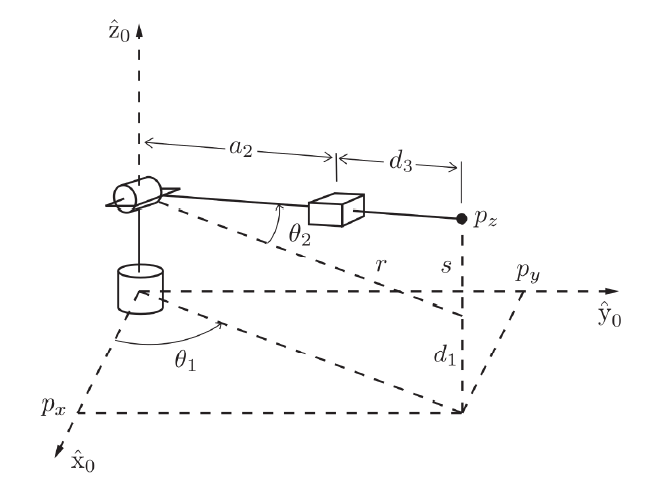

#### 1- Classical method:

In this method we will compute the forward kinematic equations of the robot manually and then get the partial derivatives of each component with respect to the joint variables:


$$\begin{array}{l}
P_x =\left(a_2 +d_3 \right)\cos \left(\theta_1 \right)\cos \left(\theta_2 \right)\\
P_y =\left(a_2 +d_3 \right)\sin \left(\theta_1 \right)\cos \left(\theta_2 \right)\\
P_z =d_1 +\left(a_2 +d_3 \right)\sin \left(\theta_2 \right)
\end{array}$$


So the jacobian matrix will look like this:


$$J=\left\lbrack \begin{array}{ccc}
\frac{\partial }{\partial \theta_1 }P_x  & \frac{\partial }{\partial \theta_2 }P_x  & \frac{\partial }{\partial d_3 }P_x \\
\frac{\partial }{\partial \theta_1 }P_y  & \frac{\partial }{\partial \theta_2 }P_y  & \frac{\partial }{\partial d_3 }P_y \\
\frac{\partial }{\partial \theta_1 }P_z  & \frac{\partial }{\partial \theta_2 }P_z  & \frac{\partial }{\partial d_3 }P_z 
\end{array}\right\rbrack$$


Let's implement!

syms theta1 theta2 d1 a2 d3
px = (a2+d3)*cos(theta1)*cos(theta2);
py = (a2+d3)*sin(theta1)*cos(theta2);
pz = d1 - (a2+d3)*sin(theta2);

O = [px; py; pz];
J_classical = [diff(O,theta1) diff(O,theta2) diff(O,d3)]

$$J\_classical = \left(\begin{array}{ccc} -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{2}\right) \end{array}\right)$$

#### 2- Skew Theory

In this approach we need to compute the tranformation matrix to every joint in the robot as we will be using the following matrices:

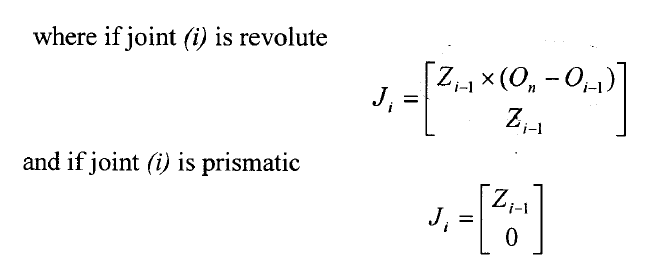

So, let's get all the transformation matrices!

% Tranformation matrices:
T0 = eye(4);
T1 = Rz(theta1)*Tz(d1);
T2 = T1*Ry(theta2)*Tx(a2);
T3 = T2*Tx(d3);

% Joint axis vector:
Z0 = [0 0 1]';
Z0x = [0 -1 0; 1 0 0; 0 0 0];
Z1 = T1(1:3,1:3)*[0 1 0]';
Z1x = [0 -Z1(3) Z1(2); Z1(3) 0 -Z1(1); -Z1(2) Z1(1) 0];
Z2 = T2(1:3,1:3)*[1 0 0]';

Now let's find the jacobian columns

% joint 1 is revolute
J1 = [Z0x*(T3(1:3,4)-T0(1:3,4)); Z0];
% joint 2 is revolute
J2 = [Z1x*(T3(1:3,4)-T1(1:3,4)); Z1];
% joint 3 is prismatic
J3 = [Z2; zeros(3,1)];
J_Skew_full = [J1 J2 J3];
J_Skew = simplify(J_Skew_full(1:3,1:3))

$$J\_Skew = \left(\begin{array}{ccc} -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{2}\right) \end{array}\right)$$

#### 3 - Numerical Method:

% Forward
T = Rz(theta1)*Tz(d1)*Ry(theta2)*Tx(a2)*Tx(d3);
R_inv = [inv(T(1:3,1:3)) zeros(3, 1); 0 0 0 1];

% J1
H1 = Rzd(theta1)*Tz(d1)*Ry(theta2)*Tx(a2)*Tx(d3)*R_inv;
J1 = [H1(1:3,4); H1(3,2); H1(1,3); H1(2,1)];

% J2
H2 = Rz(theta1)*Tz(d1)*Ryd(theta2)*Tx(a2)*Tx(d3)*R_inv;
J2 = [H2(1:3,4); H2(3,2); H2(1,3); H2(2,1)];

% J3
H3 = Rz(theta1)*Tz(d1)*Ry(theta2)*Tx(a2)*Txd(d3)*R_inv;
J3 = [H3(1:3,4); H3(3,2); H3(1,3); H3(2,1)];

J = [J1 J2 J3];
J_Numerical =simplify(J(1:3,1:3))

$$J\_Numerical = \left(\begin{array}{ccc} -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(\theta_{2}\right) \end{array}\right)$$

#### Testing the produced Jacobian matrices if they are the same:

disp("First test");

First test


J_classic_J_skew = simplify(J_classical - J_Skew)

$$J\_classic\_J\_skew = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

disp("Second test");

Second test


J_classic_J_Numerical = simplify(J_classical - J_Numerical)

$$J\_classic\_J\_Numerical = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

disp("Third test");

Third test


J_Skew_J_Numerical = simplify(J_Skew - J_Numerical)

$$J\_Skew\_J\_Numerical = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Let's further test one of the Jacobians (since they are all the same), and try to find the required joints to reach to a certain positions in space (inverse):

% specify desired positoin here and robot parameters
d1 = 175;
a2 = 250;
desiredPosition = [300; 300; 240];

% set initial angles
q = [0; 0; 0];

Now let's loop to find the solution

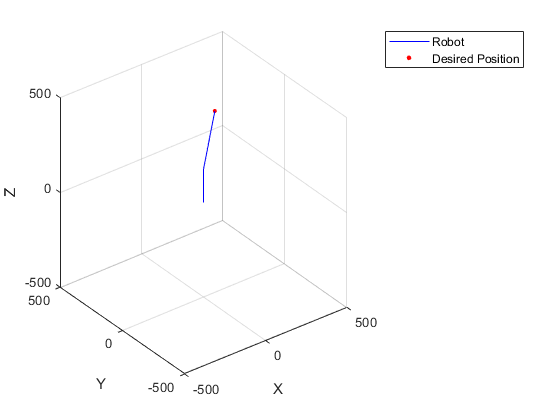

% specify number of iterations
iterations = 10;

for i = 1:iterations
    clf
    
    O3 = [(a2+q(3))*cos(q(1))*cos(q(2)); (a2+q(3))*sin(q(1))*cos(q(2)); d1 + (a2+q(3))*sin(q(2))];
    O2 = [(a2)*cos(q(1))*cos(q(2)); (a2)*sin(q(1))*cos(q(2)); d1 + (a2)*sin(q(2))];
    O1 = [0; 0; d1];
    O0 = [0; 0; 0];
    O = [O0 O1 O2 O3];
    
    J = [-cos(q(2))*sin(q(1))*(a2+q(3)) -cos(q(1))*sin(q(2))*(a2+q(3)) cos(q(1))*cos(q(2))
         cos(q(1))*cos(q(2))*(a2+q(3)) -sin(q(1))*sin(q(2))*(a2+q(3))  cos(q(2))*sin(q(1))
                    0                           cos(q(2))*(a2+q(3))          sin(q(2))    ];
    
    q = q + inv(J)*(desiredPosition - O3);
    
    % Plotting
    plot3(O(1,:),O(2,:),O(3,:),'b')
    hold on
    plot3(desiredPosition(1), desiredPosition(2), desiredPosition(3),'.r','Markersize',10)
    grid on
    xlim([-500 500]), ylim([-500 500]), zlim([-500 500]),xlabel('X'),ylabel('Y'),zlabel('Z')
    legend("Robot","Desired Position")
    drawnow
end

## Question 4:

### Singularities

for singularity calculations, let's use the lengthes d1 and a2 provided in the above simulation.

J_classical = subs(J_classical, 'd1', d1);
J_classical = subs(J_classical, 'a2', a2)

$$J\_classical = \left(\begin{array}{ccc} -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(d_{3}+250\right) & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(d_{3}+250\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(d_{3}+250\right) & -\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(d_{3}+250\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ 0 & -\cos\left(\theta_{2}\right)\,\left(d_{3}+250\right) & -\sin\left(\theta_{2}\right) \end{array}\right)$$

Now let's compute the determinant of the jacobian matrix and let it equal to 0, which is the case when we have singularities.

sing = det(J_classical) == 0;

Now let's use the function solve to find the values of theta1, theta2 and d3 that will cause singularity

[singTheta1 singTheta2 singD3] = solve(sing,[theta1 theta2 d3])

$$singTheta1 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

$$singTheta2 = \left(\begin{array}{c} 0\\ \frac{\pi }{2} \end{array}\right)$$

$$singD3 = \left(\begin{array}{c} -250\\ 0 \end{array}\right)$$

As expected we got 2 cases for singularities in this robot.

#### Case #1

The first case happens when $d_3 =-250=-a_2$, because at this configuration the angles $\theta_1$and $\theta_2$ could be of any value and the robot's end-effector will still be at the same point as seen in the following illustration:

**NOTE: THE RED DOT REFERS TO THE END-EFFECTOR**

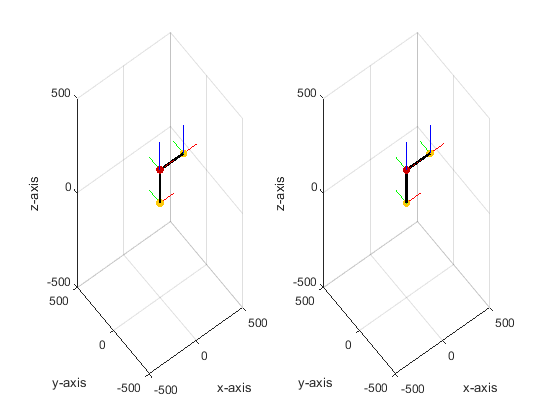

for i = 0:30:360
    clf
    % rotating theta1 only
    s(1) = subplot(1,2,1);
    FK(i,0,-250,1);
    % rotating theta2 only
    s(2) = subplot(1,2,2);
    FK(0,i,-250,1);
    
    xlim(s,[-500 500]), ylim(s,[-500 500]), zlim(s,[-500 500])
    drawnow
end

#### Case #2:

The second case is similar to the previous one; however, this time, the joint that causes the singularity effect is the second revolute joint $\theta_2$. In this case, the second link will be folded onto the first one as in this case $\theta_2 =90\;\;\textrm{or}-90$. Here, no matter what the value of $\theta_1$is, the robot's end-effector will still be at the same location as illustrated below (d3 will be fixed)

**NOTE: THE RED DOT REFERS TO THE END-EFFECTOR**

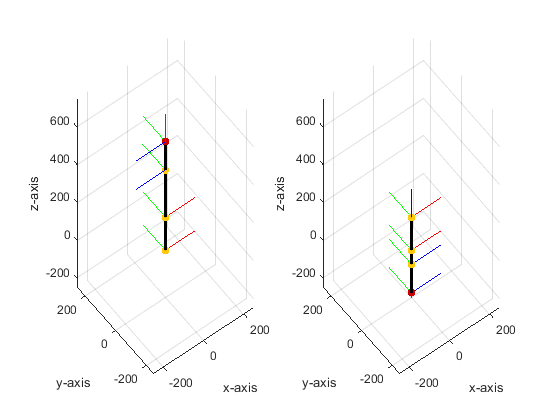

for i = 0:30:360
    clf
    % rotating theta1 only
    s(1) = subplot(1,2,1);
    FK(i,90,150,1);
    % rotating theta2 only
    s(2) = subplot(1,2,2);
    FK(i,-90,150,1);
    
    xlim(s,[-250 250]), ylim(s,[-250 250]), zlim(s,[-250 750])
    drawnow
end

## Question 5:

### Velocity of End-Effector

The jacobina matrix will be used In order to compute the velcoity of the end effector in space. The following formula will be used for this task:


$$\dot{X} =J\cdot \dot{q}$$


Where $\dot{X}$ is a vector of end-effector velocities along the x, y and z frames, and $\dot{q}$ is a vector of the velocities of the joints. Considering the case where:


$$\begin{array}{l}
\theta_1 =\sin \left(t\right)\\
\theta_2 =\cos \left(2t\right)\\
\textrm{d3}=\sin \left(3t\right)
\end{array}$$


we can get the $\dot{q}$ vector to be:


$$\dot{q} =\left\lbrack \begin{array}{c}
\cos \left(t\right)\\
=-2\sin \left(2t\right)\\
3\cos \left(3t\right)
\end{array}\right\rbrack$$


So let's visualize the velocity of the tool frame!

syms t
theta1_t = sin(t);
theta2_t = cos(2*t);
d3_t = sin(3*t);

q_dot = diff([theta1_t; theta2_t; d3_t], t);
X_dot = simplify(J_Skew_full*q_dot)

$$X\_dot = \begin{array}{l} \left(\begin{array}{c} 3\,\cos\left(3\,t\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\cos\left(t\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\left(a_{2}+d_{3}\right)+\sin\left(2\,t\right)\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sigma_{1}\\ 3\,\cos\left(3\,t\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)+\cos\left(t\right)\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\left(a_{2}+d_{3}\right)+\sin\left(2\,t\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\sigma_{1}\\ \sin\left(2\,t\right)\,\cos\left(\theta_{2}\right)\,\sigma_{1}-3\,\cos\left(3\,t\right)\,\sin\left(\theta_{2}\right)\\ 2\,\sin\left(2\,t\right)\,\sin\left(\theta_{1}\right)\\ -2\,\sin\left(2\,t\right)\,\cos\left(\theta_{1}\right)\\ \cos\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,a_{2}+2\,d_{3} \end{array}$$

So the vector X_dot now represents the velocity of the tool frame with time. Let's now look at the graphs for the change of velocity of both the joints and the tool frame with time.

clear omega1 omega2 d3_dot X_dot
i = 0;
a2 = 1;
d1 = 1;
time = 0:0.1:10;
for t=time
    i = i+1;
    theta1 = sin(t); theta2 = cos(2*t); d3 = sin(3*t);
    
    X_dot(:,i) = [3*cos(3*t)*cos(theta1)*cos(theta2) + 2*sin(2*t)*cos(theta1)*sin(theta2)*(d3 + a2) - cos(t)*cos(theta2)*sin(theta1)*(d3 + a2);
             3*cos(3*t)*cos(theta2)*sin(theta1) + 2*sin(2*t)*sin(theta1)*sin(theta2)*(d3 + a2) + cos(t)*cos(theta1)*cos(theta2)*(d3 + a2);
                                    2*sin(2*t)*cos(theta2)*(d3 + a2) - 3*cos(3*t)*sin(theta2)                                     
                                               2*sin(2*t)*sin(theta1)
                                             - 2*sin(2*t)*cos(theta1)
                                                    cos(t)];
       
    omega1(i) = cos(t); omega2(i) = -2*sin(2*t); d3_dot(i) = 3*cos(3*t);
end


Now let's plot the results:

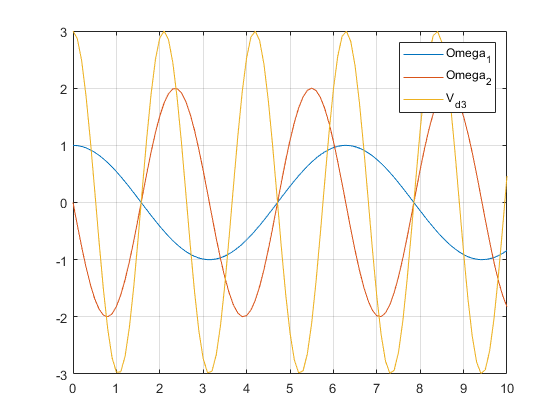

figure
plot(time,omega1)
hold on
plot(time,omega2)
hold on
plot(time,d3_dot)
grid on
legend("Omega_1",'Omega_2','V_d_3')

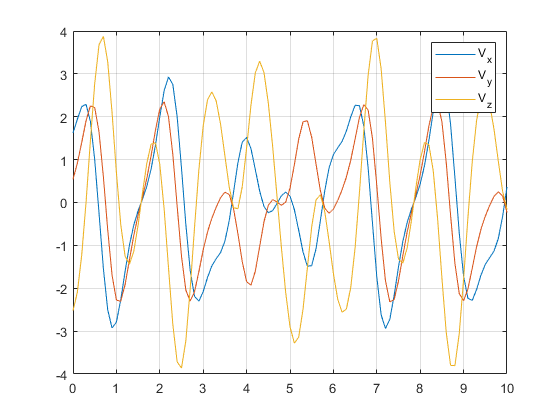

figure
plot(time,X_dot(1,:))
hold on
plot(time,X_dot(2,:))
hold on
plot(time,X_dot(3,:))
grid on
legend('V_x','V_y','V_z')

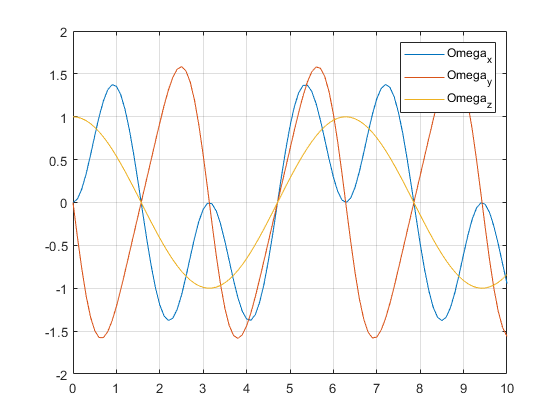

figure
plot(time,X_dot(4,:))
hold on
plot(time,X_dot(5,:))
hold on
plot(time,X_dot(6,:))
grid on
legend('Omega_x','Omega_y','Omega_z')